%import Data
cd C:\Users\sdgeo\Dropbox\Own\Graduate-School\First_Semester\COMP_775\Workspace\Final_Project\Comp_775_Final_Project;
correct_pdms = load('data\raw_matlab\correctpdms.mat')

correct_pdms = struct with fields:
    correctpdms: [128×32 double]


grey_images = load('data\raw_matlab\greyimages.mat')

grey_images = struct with fields:
    greyimages: [65536×32 int16]


data_location = ['data\raw_images'];


%For every image we need to isolate 
cd C:\Users\sdgeo\Dropbox\Own\Graduate-School\First_Semester\COMP_775\Workspace\Final_Project\Comp_775_Final_Project\data\raw_images\;
grey_image = grey_images.greyimages(:,2)

grey_image = 65536×1 int16 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


pdms_values = correct_pdms.correctpdms(:,2)

pdms_values =   125.9875
  164.2935
  128.6220
  163.8604
  130.9786
  163.1561
  133.3827
  162.2800
  135.4508
  161.1028


i = 1;
j = 1;

data = print_image_data(grey_image,correct_pdms);
writetable(data,'image_table_lookup_2.csv','Delimiter',',') 

%make a matrix for holding image name and pdm_values
pdm_image_table = table({'Filename'}, 0,0, 0,0,0,0,0,0)

pdm_image_table = 1×9 table
       Var1       Var2    Var3    Var4    Var5    Var6    Var7    Var8    Var9
    __________    ____    ____    ____    ____    ____    ____    ____    ____

    'Filename'    0       0       0       0       0       0       0       0   


%Shape the initial dataset
image_square = reshape(grey_image,256,256)

image_square = 256×256 int16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

x = pdms_values(1:2:end)

x =   125.9875
  128.6220
  130.9786
  133.3827
  135.4508
  137.3056
  139.0887
  140.7965
  141.7773
  140.1686


y = pdms_values(2:2:end)

y =   164.2935
  163.8604
  163.1561
  162.2800
  161.1028
  159.6712
  158.2550
  156.6202
  154.5693
  151.9973


points = [x,y]

points =   125.9875  164.2935
  128.6220  163.8604
  130.9786  163.1561
  133.3827  162.2800
  135.4508  161.1028
  137.3056  159.6712
  139.0887  158.2550
  140.7965  156.6202
  141.7773  154.5693
  140.1686  151.9973




name = ['corpus_image_' 'original_' int2str(i) '_' 'version_' int2str(j) '.jpeg']

name = 'corpus_image_original_1_version_1.jpeg'

image_name = {name}

image_name = 1×1 cell array
    {'corpus_image_original_1_version_1.jpeg'}


imwrite(mat2gray(image_square), name_file)

abbreviated_point_array = get_point_array(points,4,1)

abbreviated_point_array =   125.9875  164.2935  151.5128  150.4330  122.0605  170.2946   92.1685  159.9536


x1 = abbreviated_point_array(1)

x1 = 125.9875

y1 = abbreviated_point_array(2)

y1 = 164.2935

x2 = abbreviated_point_array(3)

x2 = 151.5128

y2 = abbreviated_point_array(4)

y2 = 150.4330

x3 = abbreviated_point_array(5)

x3 = 122.0605

y3 = abbreviated_point_array(6)

y3 = 170.2946

x4 = abbreviated_point_array(7)

x4 = 92.1685

y4 = abbreviated_point_array(8)

y4 = 159.9536


next_row = {image_name,x1,y1,x2,y2,x3,y3,x4,y4}

next_row = 1×9 cell array
    {1×1 cell}    {[125.9875]}    {[164.2935]}    {[151.5128]}    {[150.4330]}    {[122.0605]}    {[170.2946]}    {[92.1685]}    {[159.9536]}


pdm_image_table = [pdm_image_table;next_row]

pdm_image_table = 3×9 table
                      Var1                       Var2      Var3      Var4      Var5      Var6      Var7      Var8      Var9 
    ________________________________________    ______    ______    ______    ______    ______    ______    ______    ______

    'Filename'                                       0         0         0         0         0         0         0         0
    'corpus_image_original_1_version_1.jpeg'    125.42    153.18    156.93    144.09    118.86    156.69     90.68    128.89
    'corpus_image_original_1_version_1.jpeg'    125.99    164.29    151.51    150.43    122.06    170.29    92.168    159.95


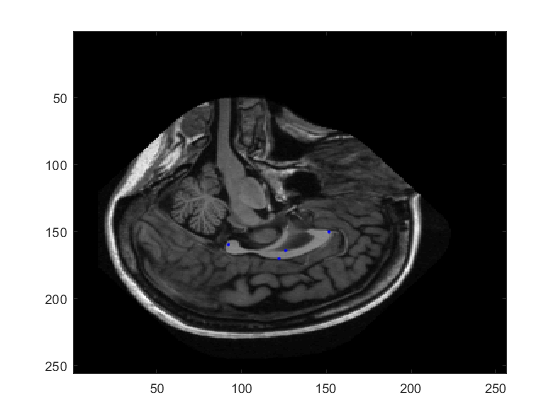

imagesc(image_square),colormap('gray');
hold on;
plot(abbreviated_point_array(1:2:end),abbreviated_point_array(2:2:end), 'b.');
hold off;

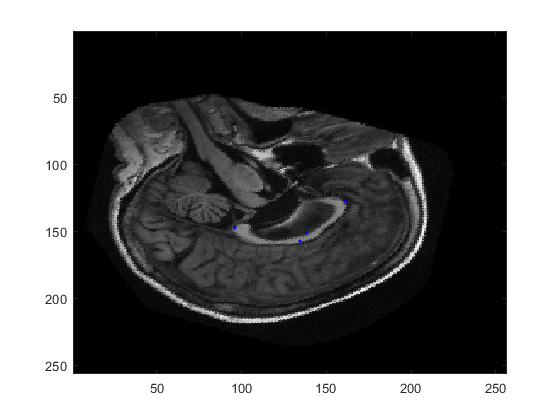

grey_image = grey_images.greyimages(:,i);
pdms_values = correct_pdms.correctpdms(:,i);
image_square = reshape(grey_image,256,256);
x = pdms_values(1:2:end);
y = pdms_values(2:2:end);
points = [x,y];

current_angle = 30;

name = ['corpus_image_' 'original_' int2str(i) '_' 'angle_' current_angle '.jpg'];
image_name = {name};

current_image = imrotate(image_square,current_angle,'crop');
rotated_points = rotate_pdm_values(points,current_angle);

%imwrite(mat2gray(current_image), name)

abbreviated_point_array = get_point_array(rotated_points,4,1);

imagesc(current_image),colormap('gray');
hold on;
plot(abbreviated_point_array(1:2:end),abbreviated_point_array(2:2:end), 'b.');
hold off;


grey_rotated_1 = imrotate(image_square,5,'crop')

grey_rotated_1 = 256×256 int16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

rotated_points_1 = rotate_pdm_values(points,5)

rotated_points_1 =   129.1583  164.3308
  131.7451  163.6697
  134.0313  162.7627
  136.3500  161.6804
  138.3075  160.3275
  140.0305  158.7397
  141.6834  157.1734
  143.2423  155.3960
  144.0405  153.2674
  142.2138  150.8455


abbreviated_point_array = get_point_array(rotated_points_1,4,1)

abbreviated_point_array =   129.1583  164.3308  153.3784  148.2983  125.7693  170.6513   95.0898  162.9549


x1 = abbreviated_point_array(1)

x1 = 129.1583

y1 = abbreviated_point_array(2)

y1 = 164.3308

x2 = abbreviated_point_array(3)

x2 = 153.3784

y2 = abbreviated_point_array(4)

y2 = 148.2983

x3 = abbreviated_point_array(5)

x3 = 125.7693

y3 = abbreviated_point_array(6)

y3 = 170.6513

x4 = abbreviated_point_array(7)

x4 = 95.0898

y4 = abbreviated_point_array(8)

y4 = 162.9549

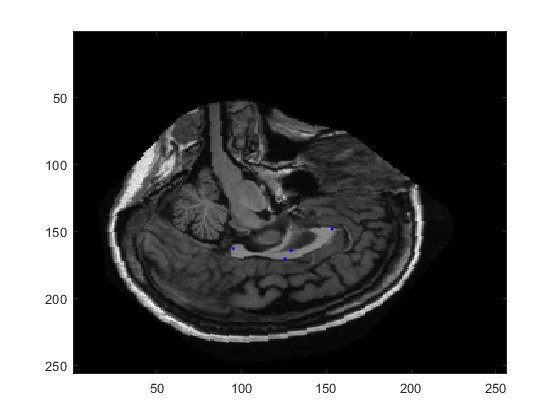

imagesc(grey_rotated_1),colormap('gray');
hold on;
plot(abbreviated_point_array(1:2:end),abbreviated_point_array(2:2:end), 'b.');
hold off;

grey_rotated_2 = imrotate(grey_rotated_1,90)

grey_rotated_2 = 256×256 int16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

rotated_points_2 = rotate_pdm_values(rotated_points_1)

rotated_points_2 =   130.5840  102.8154
  127.6796  102.3107
  124.4857  102.8466
  121.3552  103.2454
  118.4530  104.0495
  115.4936  104.9846
  112.5790  105.9838
  109.7424  107.4774
  107.4173  109.1709
  108.0836  116.0409


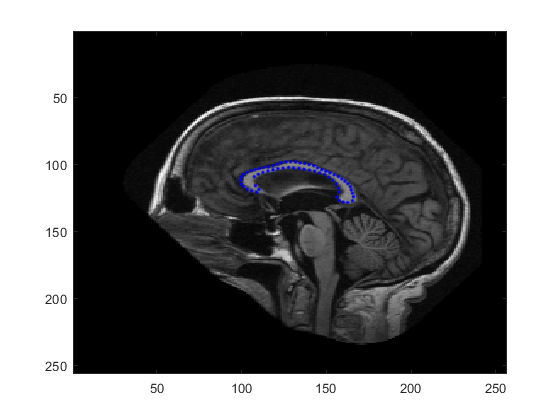

imagesc(grey_rotated_2),colormap('gray');
hold on;
plot(rotated_points_2(:,1),rotated_points_2(:,2), 'b.');
hold off;

grey_rotated_3 = imrotate(grey_rotated_2,90)

grey_rotated_3 = 256×256 int16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

rotated_points_3 = rotate_pdm_values(rotated_points_2)

rotated_points_3 =   102.8154  125.4160
  102.3107  128.3204
  102.8466  131.5143
  103.2454  134.6448
  104.0495  137.5470
  104.9846  140.5064
  105.9838  143.4210
  107.4774  146.2576
  109.1709  148.5827
  116.0409  147.9164


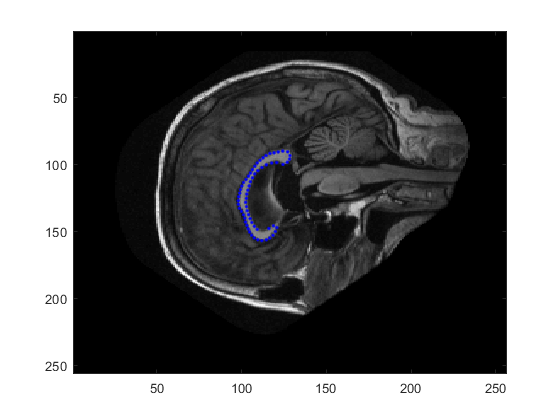

imagesc(grey_rotated_3),colormap('gray');
hold on;
plot(rotated_points_3(:,1),rotated_points_3(:,2), 'b.');
hold off;


matrix = [dot(x_norm,x_norm), dot(x_norm,y_norm); dot(x_norm,y_norm), dot(y_norm,y_norm)]

matrix =    1.0e+04 *

    3.0543    0.4142
    0.4142    0.4595


[v,d] = eig(matrix)

v =     0.1539   -0.9881
   -0.9881   -0.1539


d =    1.0e+04 *

    0.3950         0
         0    3.1189



eigenvalue_vector = sum(d)

eigenvalue_vector =    1.0e+04 *

    0.3950    3.1189


[m,larger_index] = max(eigenvalue_vector)

m = 3.1189e+04

larger_index = 2

[m,smaller_index] = min(eigenvalue_vector)

m = 3.9495e+03

smaller_index = 1

rotation_pre_matrix = reshape([v(:,larger_index),v(:,smaller_index)], 2,2)

rotation_pre_matrix =    -0.9881    0.1539
   -0.1539   -0.9881


iem = [v(:,larger_index),v(:,smaller_index)]

iem =    -0.9881    0.1539
   -0.1539   -0.9881


rotate_180 = [-1,0;0,-1]

rotate_180 =     -1     0
     0    -1


rotated_points = (point_space * transpose(rotation_pre_matrix)) * rotate_180;
x_final = rotated_points(:,1)

x_final =     1.7099
    4.5021
    7.7404
   10.8950
   13.8863
   16.9544
   19.9881
   23.0207
   25.5788
   25.9777


y_final = rotated_points(:,2)

y_final =     6.9999
    7.9455
    7.9076
    7.9953
    7.6474
    7.1789
    6.6402
    5.6009
    4.2855
   -2.6052


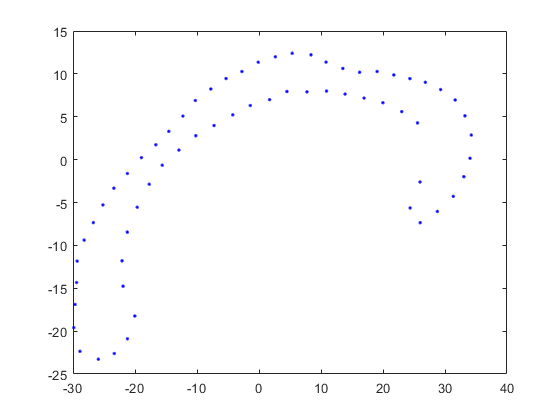

final_pdm = [];

for i = 1:(length(x_final))
    final_pdm = [final_pdm, x_final(i), y_final(i)]  ;  
end
final_pdm = reshape(final_pdm,2*length(x),1);

plot(final_pdm(1:2:end),final_pdm(2:2:end), 'b.');

pdm = correct_pdms.correctpdms(:,1)

pdm =   125.4160
  153.1846
  128.3204
  153.6893
  131.5143
  153.1534
  134.6448
  152.7546
  137.5470
  151.9505


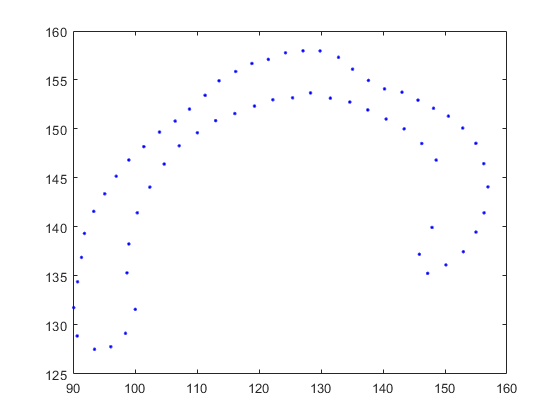

normalized_pdm = normalize_pdm_object(pdm);

plot(pdm(1:2:end),pdm(2:2:end), 'b.')

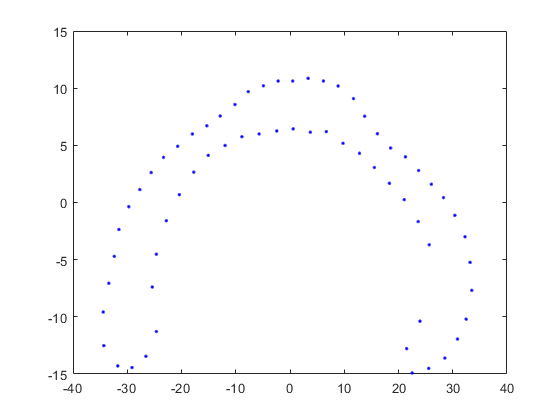

image_data = 65536×32 int16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

normed_data =     3.7257
    4.9590
   -2.3583
    8.8551
  -33.7689
  -11.4318
   35.6156
   -6.9374
  -21.5653
    1.3246


normed_data =     3.7257    2.9846
    4.9590    1.7279
   -2.3583   -2.0182
    8.8551    8.1111
  -33.7689  -31.0802
  -11.4318   -7.8829
   35.6156   32.2863
   -6.9374   -5.7199
  -21.5653  -17.4020
    1.3246   -1.4926


normed_data =     3.7257    2.9846    3.7976
    4.9590    1.7279    5.8138
   -2.3583   -2.0182   -2.0554
    8.8551    8.1111   10.0759
  -33.7689  -31.0802  -34.4780
  -11.4318   -7.8829  -11.5163
   35.6156   32.2863   32.2992
   -6.9374   -5.7199   -7.5263
  -21.5653  -17.4020  -20.0002
    1.3246   -1.4926    0.4335


normed_data =     3.7257    2.9846    3.7976    3.7683
    4.9590    1.7279    5.8138    6.1653
   -2.3583   -2.0182   -2.0554   -2.1864
    8.8551    8.1111   10.0759   10.6515
  -33.7689  -31.0802  -34.4780  -34.3987
  -11.4318   -7.8829  -11.5163  -12.5503
   35.6156   32.2863   32.2992   33.5898
   -6.9374   -5.7199   -7.5263   -7.7046
  -21.5653  -17.4020  -20.0002  -20.4527
    1.3246   -1.4926    0.4335    0.6890


normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594
    4.9590    1.7279    5.8138    6.1653    5.5934
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579
    8.8551    8.1111   10.0759   10.6515   10.4630
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086
   35.6156   32.2863   32.2992   33.5898   34.8687
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763
  -21.5653  -17.4020  -20.0002  -20.4527  -19.8911
    1.3246   -1.4926    0.4335    0.6890    0.1973


normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763   -9.4916
  -21.5653  -17.4020  -20.0002  -20.4527  -19.8911  -23.2159
    1.3246   -1.4926    0.4335    0.6890    0.1973    1.4596


normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763   -9.4916   -7.9500
  -21.5653  -17.4020  -20.0002  -20.4527  -19.8911  -23.2159  -19.5090
    1.3246   -1.4926    0.4335    0.6890    0.1973    1.4596   -0.4988


normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542   37.5235
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763   -9.4916   -7.9500   -7.7665
  -21.5653  -17.4020  -20.0002  -20.4527  -19.8911  -23.2159  -19.5090  -19.3592
    1.3246   -1.4926    0.4335    0.6890    0.1973    1.4596   -0.4988   -1.6387


normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542   37.5235   37.5689
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763   -9.4916   -7.9500   -7.7665   -7.4222
  -21.5653  -17.4020  -20.0002  -20.4527  -19.8911  -23.2159  -19.5090  -19.3592  -19.4252
    1.3246   -1.4926    0.4335    0.6890    0.1973    1.4596   -0.4988   -1.6387   -0.4648


normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053  -13.1890
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542   37.5235   37.5689   40.2385
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763   -9.4916   -7.9500   -7.7665   -7.4222   -8.7986
  -21.5653  -17.4020  -20.0002  -20.4527  -19.8911  -23.2159  -19.5090  -19.3592  -19.4252  -21.7306
    1.3246   -1.4926    0.4335    0.6890    0.1973    1.4596   -0.4988   -1.6

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053  -13.1890   -9.5304
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542   37.5235   37.5689   40.2385   33.6813
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763   -9.4916   -7.9500   -7.7665   -7.4222   -8.7986   -6.8467
  -21.5653  -17.4020  -20.0002  -20.4527  -19.8911  -23.2159  -19.5090  -19.3592  -19.4252  -21.73

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053  -13.1890   -9.5304  -13.2761
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542   37.5235   37.5689   40.2385   33.6813   38.8840
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763   -9.4916   -7.9500   -7.7665   -7.4222   -8.7986   -6.8467   -8.3889
  -21.5653  -17.40

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053  -13.1890   -9.5304  -13.2761   -8.7220
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542   37.5235   37.5689   40.2385   33.6813   38.8840   34.0499
   -6.9374   -5.7199   -7.5263   -7.7046   -7.1763   -9.4916   -7.950

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643  -35.4668
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053  -13.1890   -9.5304  -13.2761   -8.7220  -12.4790
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542   37.5235   37.5689   40.2385   33.6813   38.8840   34.0499   37.0000

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643  -35.4668  -33.7212
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053  -13.1890   -9.5304  -13.2761   -8.7220  -12.4790  -10.3194
   35.6156   32.2863   32.2992   33.5898   34.8687   37.2471   35.2542   37.5235

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643  -35.4668  -33.7212  -38.2213
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053  -13.1890   -9.5304  -13.2761   -8.7220  -12.4790  -10.3194  -11.7401
   35.6156   32.2863

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643  -35.4668  -33.7212  -38.2213  -36.6086
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245  -10.7053  -13.1890   -9.5304  -13.2761   -8.7220 

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116    3.1356
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222    3.2155
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997   -1.8667
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826    8.5910
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643  -35.4668  -33.7212  -38.2213  -36.6086  -30.2397
  -11.4318   -7.8829  -11.5163  -12.5503  -11.3086  -16.4558  -11.4587  -10.5245 

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116    3.1356    3.8050
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222    3.2155    5.9028
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997   -1.8667   -2.1666
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826    8.5910   11.9618
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643  -35.4668  -33.7212  -38.2213  -36.6086  -30.2397  -35.2792
  -11.4318   -7.8829  -11.5163 

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116    3.1356    3.8050    3.8645
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222    3.2155    5.9028    5.4583
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997   -1.8667   -2.1666   -2.2849
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826    8.5910   11.9618    9.8530
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643  -35.4668  -33.7212  -38.2213  -36.6086  -30.2397  

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116    3.1356    3.8050    3.8645    3.9860
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222    3.2155    5.9028    5.4583    4.7510
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997   -1.8667   -2.1666   -2.2849   -2.5645
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826    8.5910   11.9618    9.8530    9.3579
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  -33.4008  -37.4526  -32.6643  -35.4668  

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116    3.1356    3.8050    3.8645    3.9860    3.8374
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222    3.2155    5.9028    5.4583    4.7510    4.7396
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997   -1.8667   -2.1666   -2.2849   -2.5645   -2.1799
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826    8.5910   11.9618    9.8530    9.3579   10.2814
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  -34.9842  -36.5407  -34.5557  -38.5907  

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116    3.1356    3.8050    3.8645    3.9860    3.8374    3.8507
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222    3.2155    5.9028    5.4583    4.7510    4.7396    4.4910
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997   -1.8667   -2.1666   -2.2849   -2.5645   -2.1799   -2.3432
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826    8.5910   11.9618    9.8530    9.3579   10.2814   10.4367
  -33.7689  -31.0802  -34.4780  -34.3987  -33.4793  -38.0931  

normed_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116    3.1356    3.8050    3.8645    3.9860    3.8374    3.8507    3.9614
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222    3.2155    5.9028    5.4583    4.7510    4.7396    4.4910    3.6262
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997   -1.8667   -2.1666   -2.2849   -2.5645   -2.1799   -2.3432   -2.3069
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826    8.5910   11.9618    9.8530    9.3579   10.2814   10.4367    8.6425
  -33.7689  -31.0802  

train_data =     3.7257    2.9846    3.7976    3.7683    3.7594    4.2467    3.7329    3.8415    3.5367    4.0353    3.4281    3.9355    3.2986    3.7392    3.5433    3.9220    3.9116    3.1356    3.8050    3.8645    3.9860    3.8374    3.8507    3.9614
    4.9590    1.7279    5.8138    6.1653    5.5934    7.9863    4.7521    4.2279    2.7907    4.0137    3.4489    5.0708    2.6023    4.4868    4.3262    4.4861    4.7222    3.2155    5.9028    5.4583    4.7510    4.7396    4.4910    3.6262
   -2.3583   -2.0182   -2.0554   -2.1864   -2.1579   -2.7994   -2.2540   -2.4032   -2.1769   -2.3617   -2.0013   -2.3129   -2.0128   -2.2941   -2.0905   -2.2694   -2.4997   -1.8667   -2.1666   -2.2849   -2.5645   -2.1799   -2.3432   -2.3069
    8.8551    8.1111   10.0759   10.6515   10.4630   13.4488   11.0777    9.2907    9.6436    9.3540    8.6128   10.2827    8.5714   10.5369   10.1875    8.7260   10.3826    8.5910   11.9618    9.8530    9.3579   10.2814   10.4367    8.6425
  -33.7689  -31.0802  -

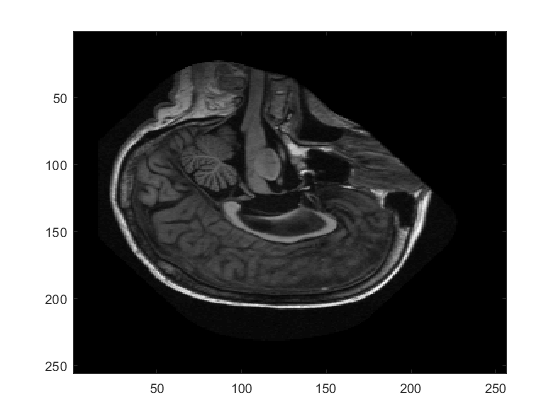

mean_subtracted_pdm =     0.3569
    0.6864
    0.6282
    1.0092
    0.9375
    0.9322
    1.2188
    0.7338
    1.2339
    0.0472


a_sigma_vector = 16.8353

a_sigma_vector =    16.8353   -5.6174


a_sigma_vector =    16.8353   -5.6174   -5.1093


a_sigma_vector =    16.8353   -5.6174   -5.1093   -1.9195


a_sigma_vector =    16.8353   -5.6174   -5.1093   -1.9195    5.6153


a_sigma_vector =    16.8353   -5.6174   -5.1093   -1.9195    5.6153    0.2282


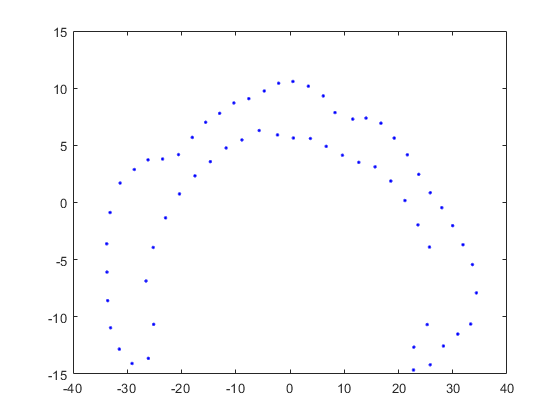

returned =     3.6811
    5.5683
   -2.2767
   10.2879
  -33.5158
  -11.7529
   33.7430
   -7.1612
  -20.5176
    0.6059


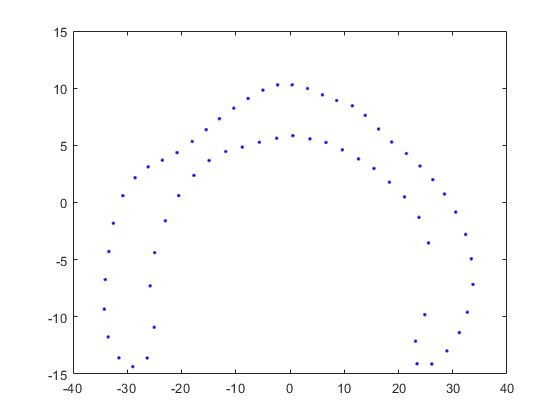

point_normals =    -0.1273   -0.9919
   -0.1838   -0.9830
   -0.2252   -0.9743
   -0.3352   -0.9421
   -0.4296   -0.9030
   -0.5919   -0.8060
   -0.7279   -0.6857
   -0.8754   -0.4835
   -0.9899    0.1418
   -0.6819    0.7314


point_tuple =   133.5835  153.6201
  136.7932  152.9161
  139.9420  152.4278
  143.1779  151.4253
  146.1224  150.2382
  149.1716  148.5528
  151.5526  146.2806
  153.7790  143.6501
  154.8142  140.3828
  152.5933  137.0758


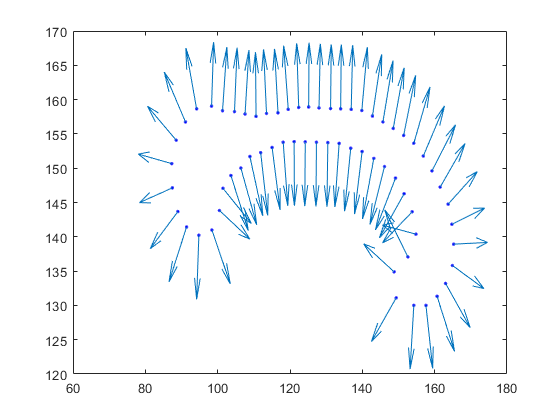

image_derivative =    1.0e-04 *

    0.1039    0.0314   -0.0945   -0.0744    0.0474    0.1071    0.0024   -0.0985   -0.0622    0.0726    0.0936   -0.0154   -0.1091   -0.0356    0.0830    0.0871   -0.0439   -0.1033   -0.0183    0.1007    0.0647   -0.0591   -0.1030    0.0113    0.1017    0.0501   -0.0822   -0.0859    0.0276    0.1092    0.0226   -0.0890   -0.0789    0.0566    0.0999    0.0061   -0.1051   -0.0565    0.0694    0.0987   -0.0234   -0.1033   -0.0374    0.0882    0.0786   -0.0398   -0.1069   -0.0117    0.0977    0.0694
   -0.0282   -0.1018   -0.0383    0.0936    0.0760   -0.0408   -0.1100   -0.0056    0.0948    0.0685   -0.0705   -0.0938    0.0082    0.1105    0.0383   -0.0777   -0.0920    0.0410    0.1014    0.0254   -0.1001   -0.0663    0.0518    0.1064   -0.0074   -0.0980   -0.0572    0.0789    0.0885   -0.0206   -0.1111   -0.0272    0.0859    0.0828   -0.0521   -0.1005   -0.0127    0.1077    0.0560   -0.0633   -0.1028    0.0202    0.0997    0.0477   -0.0880   -0.0815    0.

intensity_values =     5.9940   10.0761
    5.5497    9.1802
    5.1054    8.2844
    4.6611    7.3885
    4.2168    6.4926
    3.7725    5.5967
    3.3282    4.7008
    2.8839    3.8050
    2.4396    2.9091
    1.9954    2.0132


new_point =     5.9940   10.0761


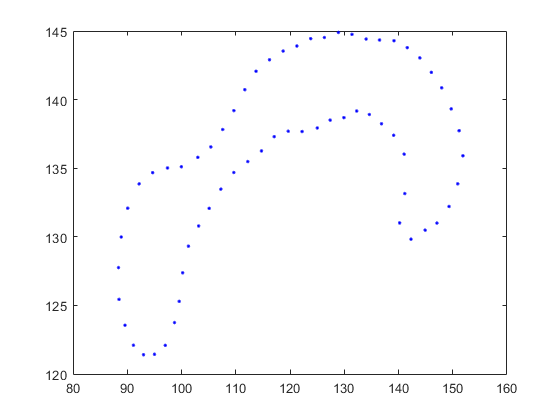

image_derivative_x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    

image_derivative_y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    

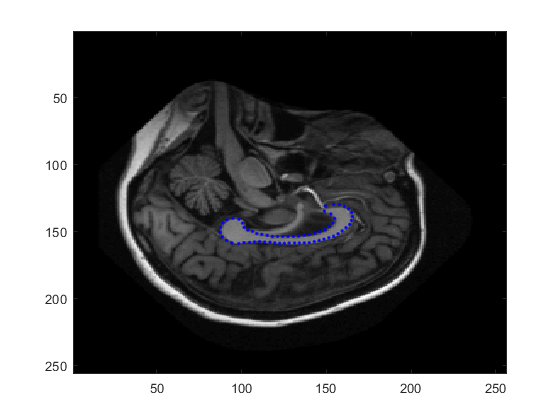

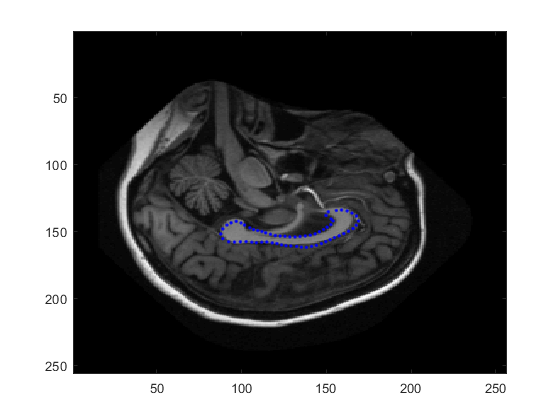

single_point =   128.0224  158.7866


its_normal =     0.0392    0.9992


gradient_list =    1.0e-03 *

   -0.6449   -0.2552


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027
    0.0003   -0.0031


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027
    0.0003   -0.0031
    0.0004   -0.0100


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027
    0.0003   -0.0031
    0.0004   -0.0100
    0.0003   -0.0032


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027
    0.0003   -0.0031
    0.0004   -0.0100
    0.0003   -0.0032
    0.0003    0.0010


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027
    0.0003   -0.0031
    0.0004   -0.0100
    0.0003   -0.0032
    0.0003    0.0010
    0.0000   -0.0010


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027
    0.0003   -0.0031
    0.0004   -0.0100
    0.0003   -0.0032
    0.0003    0.0010
    0.0000   -0.0010
    0.0002    0.0019


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027
    0.0003   -0.0031
    0.0004   -0.0100
    0.0003   -0.0032
    0.0003    0.0010
    0.0000   -0.0010
    0.0002    0.0019
    0.0003    0.0073


gradient_list =    -0.0006   -0.0003
   -0.0010    0.0014
   -0.0004    0.0027
    0.0003   -0.0031
    0.0004   -0.0100
    0.0003   -0.0032
    0.0003    0.0010
    0.0000   -0.0010
    0.0002    0.0019
    0.0003    0.0073


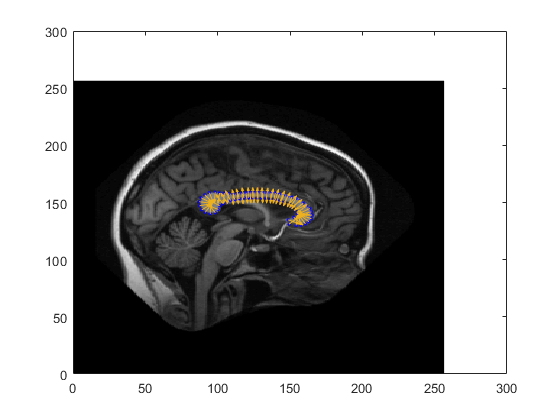

final_pdm =   133.5835
  153.6201
  136.7932
  152.9161
  139.9420
  152.4278
  143.1779
  151.4253
  145.6927
  149.3352


final_pdm =     3.7762
    3.7520
    7.0483
    3.4494
   10.2333
    3.3534
   13.5681
    2.7579
   16.3217
    0.9941


object_tuple =   -11.7767   -9.3490   -9.3707   -4.3351   -3.9552   -1.8125


final_pdm =     3.9615
    3.7959
    7.1507
    3.8619
   10.2409
    3.5897
   13.3348
    2.7970
   16.1034
    1.3496


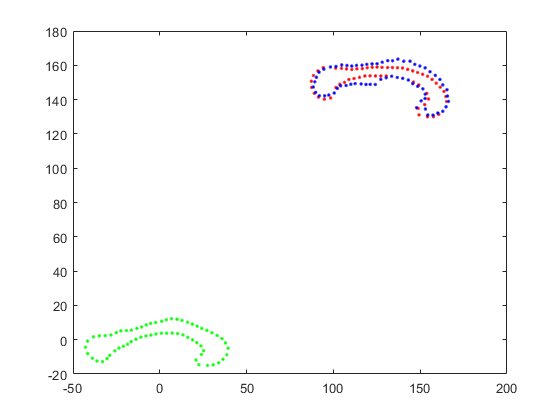

plot(normalized_pdm(1:2:end),normalized_pdm(2:2:end), 'b.');